## Read Tables


folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\"


fileName = ["TEST 0 30.1", "TEST 0 30.2", "TEST 0 60.2", "TEST 0 60.3", "TEST 0 90.1", "TEST 0 90.2", "TEST 0 120.1", "TEST 0 120.2", "TEST 0 150.1", "TEST 0 150.2", "TEST 0 180.1", "TEST 0 180.2","TEST 10 30.1","TEST 10 30.2","TEST 10 60.2","TEST 10 60.3","TEST 10 90.1","TEST 10 90.2","TEST 10 120.1","TEST 10 120.2","TEST 10 150.1","TEST 10 150.2","TEST 10 180.1","TEST 10 180.2","TEST 20 30.1","TEST 20 30.2","TEST 20 60.1","TEST 20 60.2","TEST 20 90.1","TEST 20 90.2","TEST 20 120.1","TEST 20 120.2","TEST 20 150.1","TEST 20 150.2","TEST 20 180.1","TEST 20 180.2"];
testtingSpeed = 1

testtingSpeed = 1

previousPitch = 0;
speedPlot = zeros(3,12)

speedPlot =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


for file = 1:length(fileName)
filePath = fullfile(folderPath,fileName(file) + ".csv") 

% results = readtable("C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 90.1.csv")
results = readtable(filePath);

clear aveargaeLoadcells

aveargaePitch = zeros(1,length(results.CurrentPitch1));
for i = 1:length(results.CurrentPitch1)
    aveargaePitch(i) = (results.CurrentPitch1(i) + results.CurrentPitch2(i))/2;
end

## Pitch

figure;
plot((1:length(results.Timestamp)).*10e-3, results.CurrentPitch1,'linewidth',1,'DisplayName','Rotor 1 Pitch')
hold on
plot((1:length(results.Timestamp)).*10e-3, results.TargetPitch,'-.r','linewidth',1.5,'DisplayName','Target Pitch')
plot((1:length(results.Timestamp)).*10e-3, results.CurrentPitch2,'linewidth',1,'DisplayName','Rotor 2 Pitch')
plot((1:length(results.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
ylim([-20,50])
xlim([0,length(results.CurrentPitch1)].*10e-3)
hold off
ylabel('Pitch [°]');
xlabel('Time [s]');
title(sprintf('Change of Rotor Pitch Over Time at %d rpm with a %d° pitch', results.TargetSpeed(1), results.TargetPitch(1)));
legend;
imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + fileName(file) + ".png")
dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);

## Loadcell Data

results.LoadCell1 = -(results.LoadCell1 - results.LoadCell1(1)).*0.0098;
loadcell1 = rmmissing(results.LoadCell1);
loadcell1(isoutlier(results.LoadCell1, 'mean')) = NaN;
loadcell1 = fillmissing(loadcell1, 'linear');

results.LoadCell2 = -(results.LoadCell2 - results.LoadCell2(1)).*0.0098;
loadcell2 = rmmissing(results.LoadCell2);
loadcell2(isoutlier(results.LoadCell2, 'mean')) = NaN;
loadcell2 = fillmissing(loadcell2, 'linear');

results.LoadCell3 = -((results.LoadCell3) - (results.LoadCell3(1))).*0.0098.*0.9;
loadcell3 = rmmissing(results.LoadCell3);
loadcell3(isoutlier(results.LoadCell3, 'mean')) = NaN;
loadcell3 = fillmissing(loadcell3, 'linear');

results.LoadCell4 = -((results.LoadCell4) - (results.LoadCell4(1))).*0.0098.*0.8;
loadcell4 = rmmissing(results.LoadCell4);
loadcell4(isoutlier(results.LoadCell4, 'mean')) = NaN;
loadcell4 = fillmissing(loadcell4, 'linear');

aveargaeLoadcells = zeros(1,length(loadcell1));
for i = 1:length(loadcell1)
    aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
end
figure;
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Loadcell 1')
hold on
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Loadcell 2')
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Loadcell 3')
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Loadcell 4')
plot(linspace(0,length(results.Timestamp)*10e-3, length(aveargaeLoadcells)),aveargaeLoadcells,'DisplayName','Combined Loadcells')
xlim([0,length(results.Timestamp)*10e-3])
hold off
ylabel('Lift [N]');
xlabel('Time [s]');
title(sprintf('Unfiltered Loadcell Readings for %d rpm with a %d° pitch', results.TargetSpeed(1), results.TargetPitch(1)));
legend;

imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" + fileName(file) + ".png");
dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);
% plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell1)),loadcell1)


speed = (results.CurrentSpeed(floor(length(results.CurrentSpeed)/2)));
rotor_freq = speed * 2*pi/60/(2*pi);
period = 0.44;
fs = 1/period;   % Sampling Frequency
nyquist_freq = fs/2 ;

aliasing_freq = rotor_freq/nyquist_freq;
if aliasing_freq < 2 && aliasing_freq > 1 || aliasing_freq > 3
    aliasing_freq = 2 - aliasing_freq;
end

plot_aliais = mod(aliasing_freq,aliasing_freq - mod(aliasing_freq/1,1));

L = length(aveargaeLoadcells);         % Length of the signal
Y = fft(aveargaeLoadcells);            % Perform FFT


P2 = abs(Y/L);                     % Two-sided spectrum
P1 = P2(1:floor(L/2)+1);           % Single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1);       % Account for energy in both sides of spectrum
f = fs/L*(0:(L/2));                % Frequency axis

% abs(P2);

% Single-Sided Spectrum
plot(f, P1,"LineWidth",3,"DisplayName","FFT");
xlim([0,f(end)])
title(sprintf('Single-Sided FFT of Combined Load cell Output for %d rpm', results.TargetSpeed(1)));
xlabel('Frequency (Hz)');
ylabel('Amplitude of Combined Loadcells');
xline(plot_aliais,'--r','linewidth',2,"DisplayName",sprintf('Aliasing Frequency for %d rpm', results.TargetSpeed(1)));
legend;

set(gcf, 'Position', [100, 100, 600, 500]);
imageFilePath = fullfile(imageFolderPath,"FFT-" + fileName(file) + ".png");
dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);
cutOffFrequency = 0.2;
nOrder = 4;

[b,a] = butter(nOrder,cutOffFrequency/(fs/2));
loadcell1Filtered = filtfilt(b,a,loadcell1);
loadcell2Filtered = filtfilt(b,a,loadcell2);
loadcell3Filtered = filtfilt(b,a,loadcell3);
loadcell4Filtered = filtfilt(b,a,loadcell4);

% pitch = sgolayfilt(results.CurrentPitch2,4,111);
% figure;
% plot([1:length(results.Timestamp)],  sgolayfilt(results.CurrentPitch1,4,111))
% hold on
% plot([1:length(results.Timestamp)], results.TargetPitch)
% plot([1:length(results.Timestamp)],  sgolayfilt(results.CurrentPitch2,4,111))
% ylim([-20,45])
% hold off

aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
deltaThrust = (loadcell4Filtered+loadcell1Filtered) - (loadcell3Filtered+loadcell2Filtered);


for i = 1:length(loadcell1Filtered)
    aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
end
figure;
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Loadcell 1')
hold on
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Loadcell 2')
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Loadcell 3')
plot(linspace(0,length(results.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Loadcell 4')
plot(linspace(0,length(results.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'--r','linewidth',2, 'DisplayName','Combined Loadcells')
yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'-.b','DisplayName','Average Lift')
hold off
xlim([0,length(results.Timestamp)*10e-3])
ylabel('Lift [N]');
xlabel('Time [s]');
title(sprintf('Lift Generated at %d rpm with %d° pitch', results.TargetSpeed(1), results.TargetPitch(1)));
legend;

imageFilePath = fullfile(imageFolderPath,"Lift Generated-" + fileName(file) + ".png");
dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);

 mod(file-1,12)+1
if results.TargetPitch(1) > previousPitch
    testtingSpeed = testtingSpeed+1
    previousPitch = results.TargetPitch(1);
end 
speedPlot (testtingSpeed, mod(file-1,12)+1) = mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3*mean(aveargaeLoadcellsFiltered)))

## Combined Data

% linspace(1,length(aveargaePitch),length(aveargaeLoadcells))
% 
% figure;
% yyaxis left
% plot(1:length(aveargaePitch),interp1(linspace(1,length(aveargaePitch),length(aveargaeLoadcells)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear'))
% hold on 
% plot(1:length(aveargaePitch),sgolayfilt(results.CurrentSpeed,4,111))
% ax = gca;
% ax.YColor ="red"; % Set the left y-axis color to blue
% 
% yyaxis right
% plot(1:length(aveargaePitch),sgolayfilt(aveargaePitch,4,111))
% hold off


figure;
clear alpha
yyaxis left
plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Lift', 'LineWidth', 1.5);
hold on;
plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(results.CurrentSpeed, 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angualr Velocity', 'LineWidth', 1.5);
alpha(0); % Set transparency for better visibility
ylabel('Lift [N × 100] / Angular Velocity [rpm]');
ax = gca;
ax.YColor = 'k'; % Set color to black for consistency

yyaxis right
plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
alpha(0.2); % Set transparency
ylabel('Pitch');
ax.YColor = 'k'; % Set color to black for consistency
ylim([-10,45])
    
xlabel('Time [s]');
title('Overlay of Load Cell, Speed, and Pitch Data');
legend;
xlim([0,length(results.Timestamp)*10e-3])
% grid on;
hold off;
imageFilePath = fullfile(imageFolderPath,"Lift, speed and Pitch-" + fileName(file) + ".png");
dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
close(gcf);

% figure;
% % Get the colormap (e.g., 'jet')
% cmap = winter(length(results.CurrentSpeed));
% 
% % Normalize the speed values to the range of the colormap
% normalizedSpeed = (results.CurrentSpeed - min(results.CurrentSpeed)) / (max(results.CurrentSpeed) - min(results.CurrentSpeed));
% 
% % Plot the data with varying colors based on speed
% hold on;
% for i = 1:length(sizedLoadcells)-1
%     % Choose a color based on the normalized speed
%     colorIndex = round(normalizedSpeed(i) * (length(cmap)-1)) + 1;
%     line([i, i+1], [sizedLoadcells(i), sizedLoadcells(i+1)], 'Color', cmap(colorIndex, :), 'LineWidth', 1.5);
% end
% hold off;
% colorbar;
% colormap(winter);
% caxis([min(results.CurrentSpeed), max(results.CurrentSpeed)]);
% xlabel('Sample Index');
% ylabel('Pitch');
% title('Line Color Changing with Speed');
end

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 30.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 30.1.png"

ans = 1

speedPlot =     0.6970         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 30.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 30.2.png"

ans = 2

speedPlot =     0.6970    0.4692         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 60.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 60.2.png"

ans = 3

speedPlot =     0.6970    0.4692    1.0390         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 60.3.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 60.3.png"

ans = 4

speedPlot =     0.6970    0.4692    1.0390    1.0358         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 90.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 90.1.png"

ans = 5

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 90.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 90.2.png"

ans = 6

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 120.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 120.1.png"

ans = 7

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 120.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 120.2.png"

ans = 8

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 150.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 150.1.png"

ans = 9

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 150.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 150.2.png"

ans = 10

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 180.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 180.1.png"

ans = 11

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 0 180.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 0 180.2.png"

ans = 12

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 30.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 30.1.png"

ans = 1

testtingSpeed = 2

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 30.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 30.2.png"

ans = 2

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 60.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 60.2.png"

ans = 3

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 60.3.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 60.3.png"

ans = 4

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 90.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 90.1.png"

ans = 5

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 90.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 90.2.png"

ans = 6

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 120.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 120.1.png"

ans = 7

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 120.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 120.2.png"

ans = 8

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 150.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 150.1.png"

ans = 9

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 150.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 150.2.png"

ans = 10

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577         0         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 180.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 180.1.png"

ans = 11

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590         0
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 10 180.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 10 180.2.png"

ans = 12

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
         0         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 30.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 30.1.png"

ans = 1

testtingSpeed = 3

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301         0         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 30.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 30.2.png"

ans = 2

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913         0         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 60.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 60.1.png"

ans = 3

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965         0         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 60.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 60.2.png"

ans = 4

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745         0         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 90.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 90.1.png"

ans = 5

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697         0         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 90.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 90.2.png"

ans = 6

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006         0         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 120.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 120.1.png"

ans = 7

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155         0         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 120.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 120.2.png"

ans = 8

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155    3.9974         0         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 150.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 150.1.png"

ans = 9

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155    3.9974    5.0754         0         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 150.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 150.2.png"

ans = 10

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155    3.9974    5.0754    3.2676         0         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 180.1.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 180.1.png"

ans = 11

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155    3.9974    5.0754    3.2676    4.0243         0


filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Pitch Sweep\TEST 20 180.2.csv"

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Graphs\Pitch Graph-TEST 20 180.2.png"

ans = 12

speedPlot =     0.6970    0.4692    1.0390    1.0358    1.5238    1.5118    0.6006    0.0444    1.1684    0.0569    0.0841    0.0035
    0.5430    0.2848    1.0593    1.1349    2.4521    2.3224    1.8563    0.8885    1.8294    1.5577    0.0590   -0.0408
    0.6301    0.6913    1.1965    1.2745    2.4697    2.6006    3.4155    3.9974    5.0754    3.2676    4.0243    4.2686


% plot(1:length(speedPlot),abs(speedPlot))
figure;
lift20Deg = [speedPlot(3,1), speedPlot(3,3),speedPlot(3,5),speedPlot(3,8),speedPlot(3,9),speedPlot(3,12)]

lift20Deg =     0.6301    1.1965    2.4697    3.9974    5.0754    4.2686


sampleSpeeds = [30 60 90 120 150 180]

sampleSpeeds =     30    60    90   120   150   180


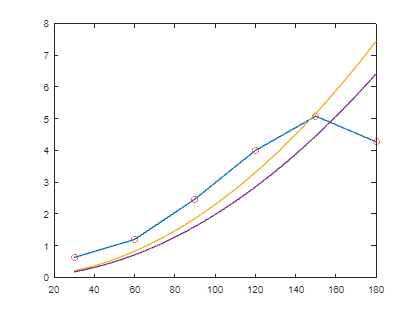

plot(sampleSpeeds, lift20Deg)
hold on
plot(sampleSpeeds, lift20Deg,'or')
fplot(@(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20), [30 180])
fplot(@(x) 0.01805 .* (x .* pi/30).^2, [30 180])
hold off



lift5Deg = [speedPlot(1,2), speedPlot(1,3),speedPlot(1,5),speedPlot(2,7),speedPlot(2,10), speedPlot(3,12) ]

lift5Deg =     0.4692    1.0390    1.5238    1.8563    1.5577    4.2686


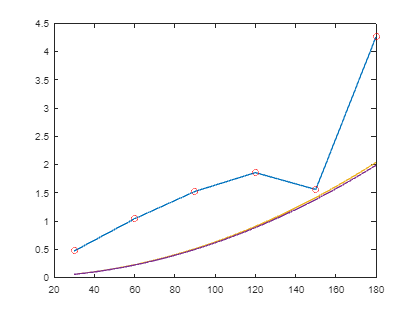

figure;
plot(sampleSpeeds, lift5Deg)
hold on
plot(sampleSpeeds, lift5Deg,'or')
fplot(@(x) 0.005598 .* (x .* pi/30).^2 + 0.0004187 .* (x .* pi/30).^2/0.2625 .*sind(5), [30 180])
fplot(@(x) 0.005598 .* (x .* pi/30).^2 , [30 180])
hold off